Metode iterative

Probleme suplimentare

## Problema 1

### Jacobi

a) Jacobi (n - mare)

format long
n = 1e4;

A = get_sparse_matrix(n);
b = A * ones(n, 1);

tic
[x, nj, err] = Jacobi(A,b,b,1e-8,n, ones(n, 1));
toc

Elapsed time is 0.007628 seconds.


err(1:nj+1)

ans =    0.444443244129931
   0.242410867342050
   0.113463598379793
   0.048699222275429
   0.020065416589972
   0.008123759251243
   0.003265342697649
   0.001308672514249
   0.000523869710141
   0.000209609764769


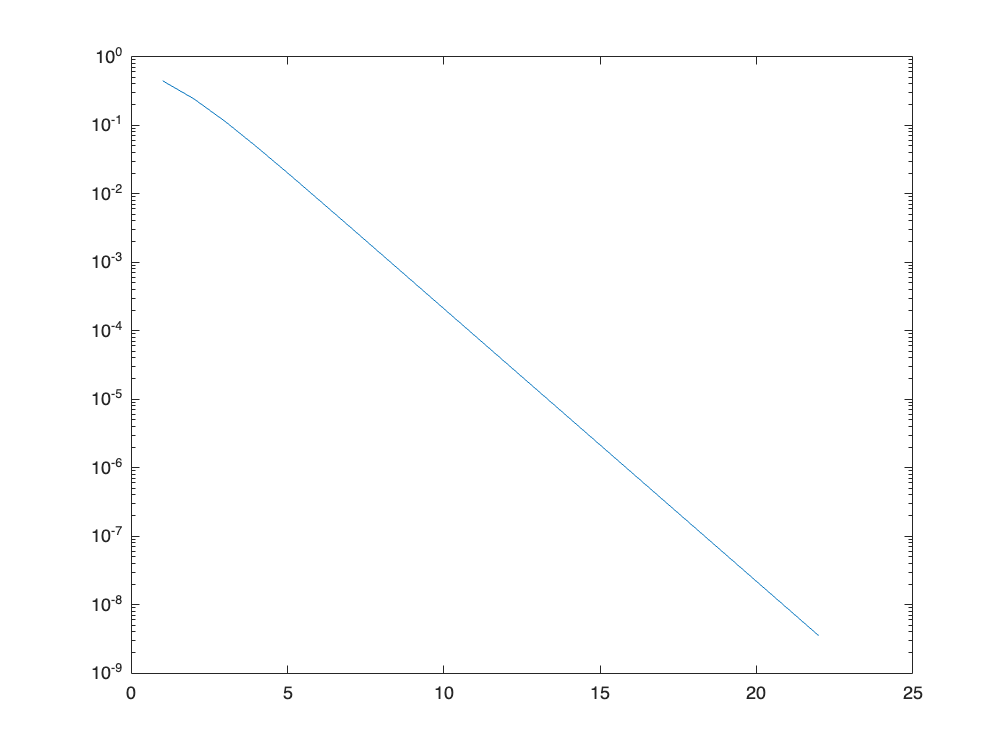

semilogy(1:nj, err(1:nj))

A = full(A);
tic
[x, nj, err] = Jacobi(A,b,b,1e-8,n);

Not enough input arguments.

Error in Jacobi (line 33)
   errors(i) = norm(exp-x)/norm(x);

toc
semilogy(1:nj, err(1:nj))

Performanta pentru n mare, la o matrice densa este mult mai slaba pentru Jacobi

b) Jacobi - n mic

n = 100;

A = get_sparse_matrix(n);
b = A * ones(n, 1);

tic
[x, nj, err] = Jacobi(A,b,b,1e-8,n);
toc
semilogy(1:nj, err(1:nj))
A = full(A);
tic
[x, nj, err] = Jacobi(A,b,b,1e-8,n);
toc
semilogy(1:nj, err(1:nj))

Pentru valori mai mici ale lui n, rezolvarea cu matrice densa este mai eficienta

### Gauss-Siedel

a) n - mare

n = 1e4;

A = get_sparse_matrix(n);
b = A * ones(n, 1);

tic
[x, nj, err] = Gauss_Seidel(A,b,b,1e-8,n);
toc
semilogy(1:nj, err(1:nj))
A = full(A);
tic
[x, nj, err] = Gauss_Seidel(A,b,b,1e-8,n);
toc
semilogy(1:nj, err(1:nj))

Si aici se poate observa ca pentru un n - mare, folosirea matricei rare, aduce beneficii clare pentru timpul de executie

b) n - mic

n = 100;

A = get_sparse_matrix(n);
b = A * ones(n, 1);

tic
[x, nj, err] = Gauss_Seidel(A,b,b,1e-8,n);
toc
semilogy(1:nj, err(1:nj))
A = full(A);
tic
[x, nj, err] = Gauss_Seidel(A,b,b,1e-8,n);
toc
semilogy(1:nj, err(1:nj))

Si in acest caz, matricea densa, se dovedeste mai rapida in aplicarea algoritmului pentru o matrice densa